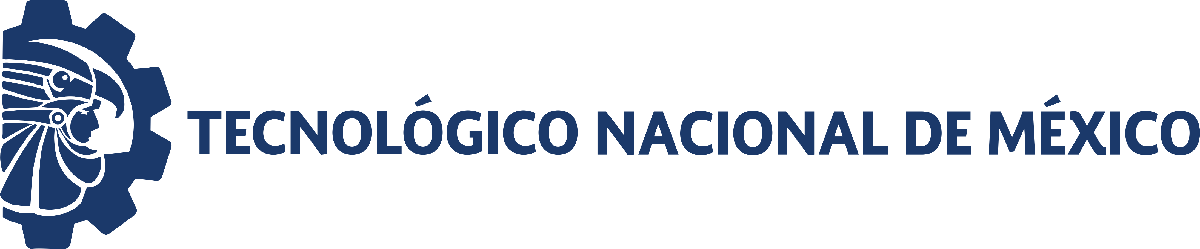                                 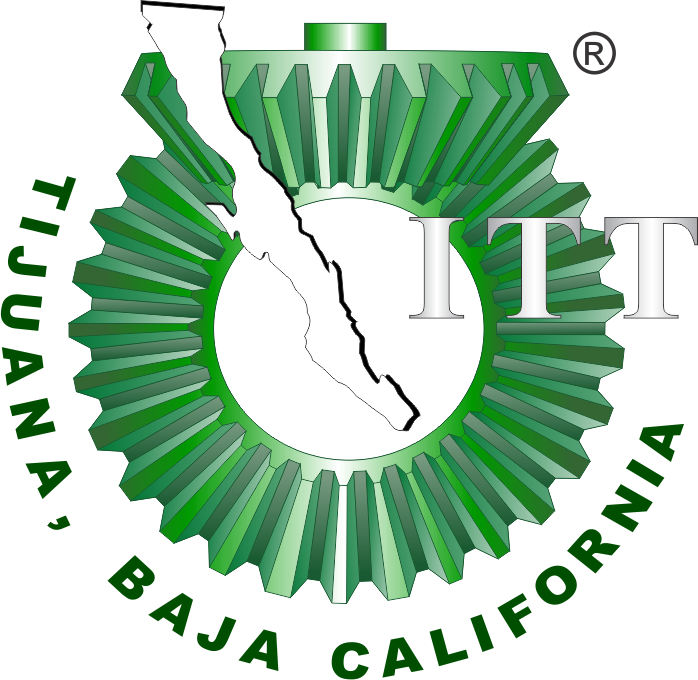

# Proyecto: Sistema optico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

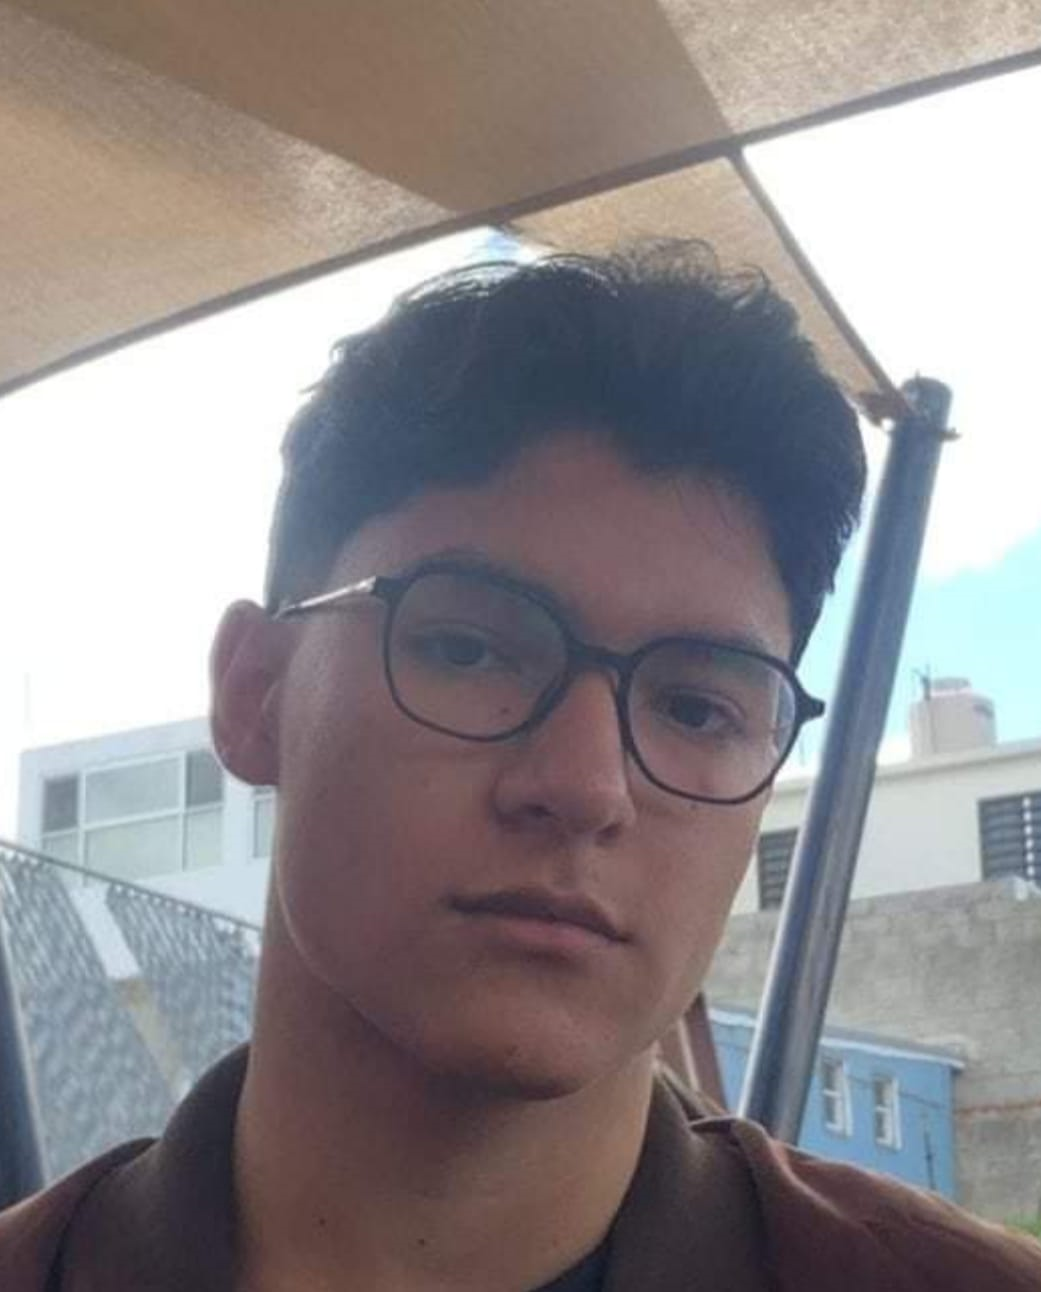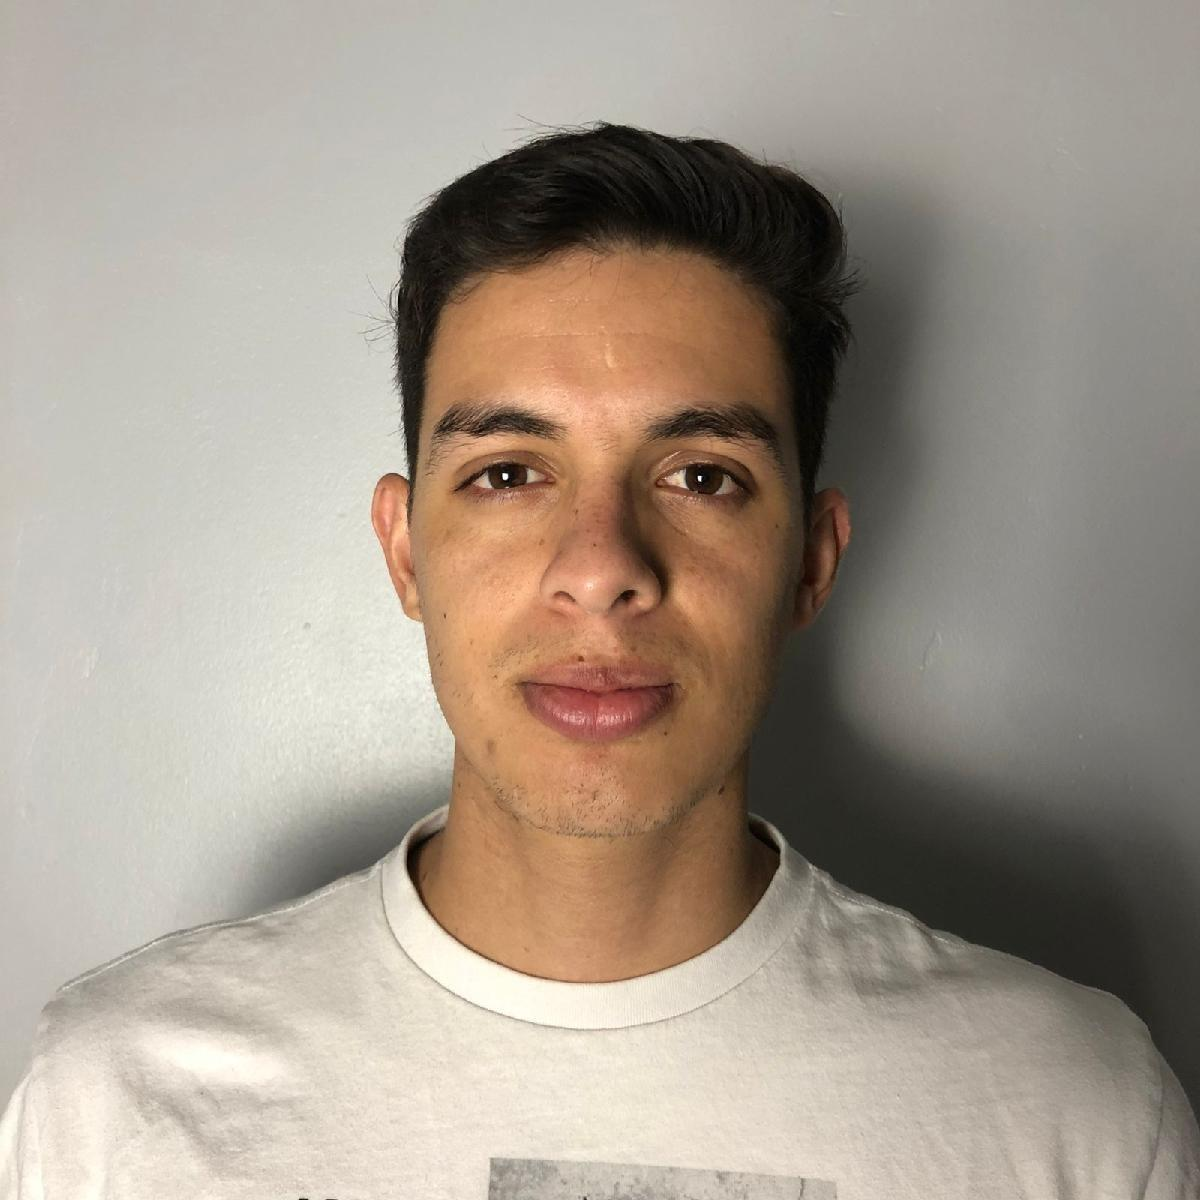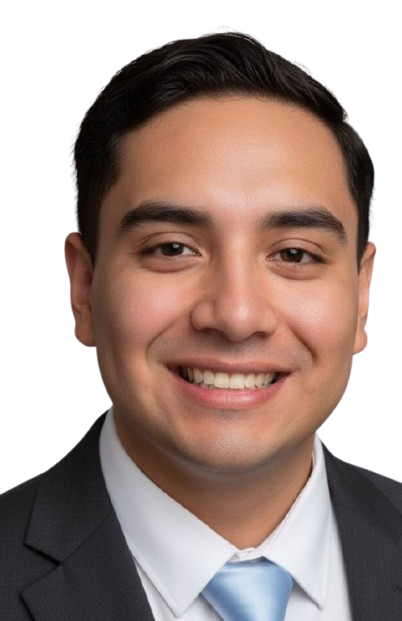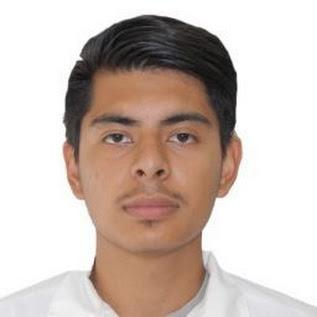

Nombre de los alumnos: Avila Sanchez German Emmanuel, Estrada Castillo Ian Enrique, Chizek Espinoza Josue, Diego Saul Lopez Islas

Número de control: 22212382, 22212250, 22211753, 22211759

Correo institucional: L22212382@tectijuana.edu.mx, L222122509@tectijuana.edu.mx, L22211753@tectijuana.edu.mx, L22211759@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Simulacion';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
Signal = 'Sistema optico';
set_param('Simulacion/Ve','Amplitude','1')
set_param('Simulacion/Ve','Bias','0')
set_param('Simulacion/Ve','Frequency','pi/2')
set_param('Simulacion/Ve','Phase','0')
set_param('Simulacion/Ve','SampleTime','0')
X = sim(file,parameters);
plotsignals(X.t,X.Vs1,X.Vs2,X.PID,Signal);

**Funcion: Respuesta a las señales**

function plotsignals(t,Vs1,Vs2,PID,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616
               0.114,0.208,0.341
               0.133,0.341,0.310
               0.569,0.392,0.235];
    colororder(mycolor)
    p = plot(t,Vs1,'--o',t,Vs2,'--+',t,PID,':',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3), 'LineWidth',3); 
    L = legend('$Control$','$Caso$','$Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V(t)$ $[V]$','Interpreter','Latex','FontSize',11)

     if Signal == "Sistema optico" 
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.05,0.1]); yticks(-0.1:0.02:2);
     end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')

    
end
